clear;
clc;

syms t
ang = 0:1:3e4;

mu = 3.986004418e14;
J2 = 1.082635854e-3;
J3 = 2.532435346e-6;
R = 6378.137e3;

% SSO
a = 7211.54e3;
n = sqrt(mu / a^3);
INC     = deg2rad(98.7);
omega   = deg2rad(30);
theta_0 = deg2rad(0);
%x0  =  6182.923072003555e3;
%y0  = - 539.9576105445875e3;
%z0  =  3528.638786215765e3;
%dx0 = -3.754637152801252e3;
%dy0 = -0.9836827412595693e3;
%dz0 =  6.428395500600019e3;
x0  = 0;
y0  = 0;
z0  = 0;
dx0 = 0;
dy0 = 0;
dz0 = 0;


nt = n*t;
cnt = cos(nt);
snt = sin(nt);
c2nt = cos(2*nt);
s2nt = sin(2*nt);
c3nt = cos(3*nt);
s3nt = sin(3*nt);

si = sin(INC);
ci = cos(INC);
sw = sin(omega);
cw = cos(omega);
s2w = sin(2*omega);
c2w = cos(2*omega);
s3w = sin(3*omega);
c3w = cos(3*omega);

## J2

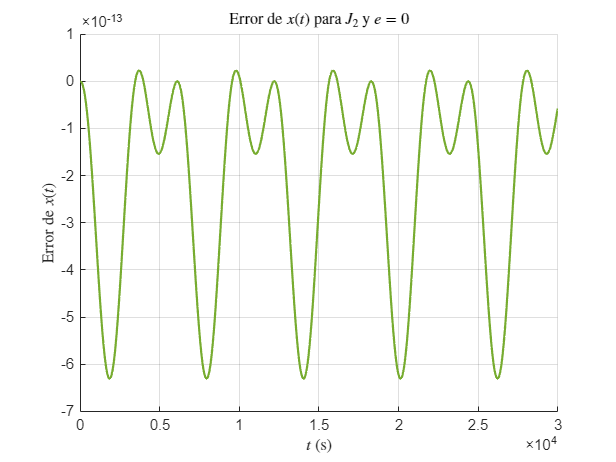

k1 = dx0/n;
k2 = x0;
K  = dy0 + 2*n*x0 - 3/(4*a)*n*J2*R^2*si^2*c2w;
Kp = y0 - 2*dx0/n - 9/(8*a)*J2*R^2*si^2*s2w;

% x
x_K = k1*snt + k2*cnt - (3*J2*R^2)/(2*a)* ...
    ( - (si^2*s2w/6)*(-s2nt + 2*snt) + ...
      (si^2*c2w/6)*(cnt - c2nt) + ...
    (1 - (3/2)*si^2)*(1 - cnt) ) + ...
    (2*K/n)*(1 - cnt);
x_B = ((n + 6*n*sin((n*t)/2)^2)/n)*x0 + (sin(n*t)/n)*dx0 + ((4*sin((n*t)/2)^2)/n)*dy0 + ((R^2*(4*sin((n*t)/2)^2*sin(INC)^2 - sin(n*t)^2*sin(INC)^2 - 6*sin((n*t)/2)^2 + 2*sin(n*t)^2*sin(INC)^2*sin(omega)^2 + 10*sin((n*t)/2)^2*sin(INC)^2*sin(omega)^2 + 2*sin(n*t)*sin(INC)^2*cos(omega)*sin(omega) - 2*cos(n*t)*sin(n*t)*sin(INC)^2*cos(omega)*sin(omega)))/(a*2))*J2;

% xdot
dx_K = n*k1*cnt - n*k2*snt + 2*K*snt - ...
        3*J2*R^2/(2*a)*(-si^2*s2w/3*(-n*c2nt + n*cnt)  + ...
        si^2*c2w/6*(-n*snt + 2*n*s2nt) + ...
        (1 - 3/2*si^2)*n*snt);
dx_B = (6*n*cos((n*t)/2)*sin((n*t)/2))*x0 + cos(n*t)*dx0 + (4*cos((n*t)/2)*sin((n*t)/2))*dy0 + ((R^2*(4*n*cos((n*t)/2)*sin((n*t)/2)*sin(INC)^2 - 2*n*cos(n*t)*sin(n*t)*sin(INC)^2 - 6*n*cos((n*t)/2)*sin((n*t)/2) + 2*n*cos(n*t)*sin(INC)^2*cos(omega)*sin(omega) + 4*n*cos(n*t)*sin(n*t)*sin(INC)^2*sin(omega)^2 + 10*n*cos((n*t)/2)*sin((n*t)/2)*sin(INC)^2*sin(omega)^2 - 2*n*cos(n*t)^2*sin(INC)^2*cos(omega)*sin(omega) + 2*n*sin(n*t)^2*sin(INC)^2*cos(omega)*sin(omega)))/(a*2))*J2;

% y
y_K = 2*k1*cnt - 2*k2*snt + ...
      3*n/(2*a)*J2*R^2 * ...
      ( si^2*s2w/3 * (c2nt/(4*n) + 2*cnt/n) + ...
      si^2*c2w * ( 1/(3*n)*snt + s2nt/(12*n) ) + ...
      2 * (1 - 3/2*si^2) * (t - snt/n) ) ...
      - 3*K*t + 4*K/n*snt + Kp;
y_B = (-6*n)*x0*t + (6*sin(n*t))*x0 + y0 + (-(4*sin((n*t)/2)^2)/n)*dx0 - 3*dy0*t + ((4*sin(n*t))/n)*dy0 + (-(R^2*(18*n*sin(INC)^2 - 24*n + 36*n*sin(INC)^2*sin(omega)^2))/(a*8))*t*J2 + (-(R^2*(24*sin(n*t) - 16*sin(n*t)*sin(INC)^2 - sin(2*n*t)*sin(INC)^2 - 40*sin(n*t)*sin(INC)^2*sin(omega)^2 + 2*sin(2*n*t)*sin(INC)^2*sin(omega)^2 + 2*sin(2*omega)*sin(n*t)^2*sin(INC)^2 + 16*sin(2*omega)*sin((n*t)/2)^2*sin(INC)^2))/(8*a))*J2;

% ydot
dy_K = -2*n*k1*snt - 2*n*k2*cnt + ...
        (3*n*J2*R^2 / (2*a)) * ...
        ( -(si^2 * s2w / 3) * (s2nt / 2 + 2*snt)  + ...
        (si^2 * c2w) * ( (1/3)*cnt + c2nt / 6 ) + ...
        2 * (1 - (3/2)*si^2) * (1 - cnt) ) - ...
        3*K + 4*K*cnt;
dy_B = dy0 + 2*n*x0 - 2*n*((dx0*sin(n*t))/n + (x0*(n + 6*n*sin((n*t)/2)^2))/n + (4*dy0*sin((n*t)/2)^2)/n + (J2*R^2*(4*sin((n*t)/2)^2*sin(INC)^2 - sin(n*t)^2*sin(INC)^2 - 6*sin((n*t)/2)^2 + 2*sin(n*t)^2*sin(INC)^2*sin(omega)^2 + 10*sin((n*t)/2)^2*sin(INC)^2*sin(omega)^2 + 2*sin(n*t)*sin(INC)^2*cos(omega)*sin(omega) - 2*cos(n*t)*sin(n*t)*sin(INC)^2*cos(omega)*sin(omega)))/(2*a)) + (3*J2*R^2*n*sin(INC)^2*cos(2*omega + 2*n*t))/(4*a) - (3*J2*R^2*n*cos(2*omega)*sin(INC)^2)/(4*a);

plotError(t,  x_K,  x_B, ang,       'Error de $x(t)$ para $J_2$ y $e = 0$', '$t$ (s)',       'Error de $x(t)$', "#77AC30");

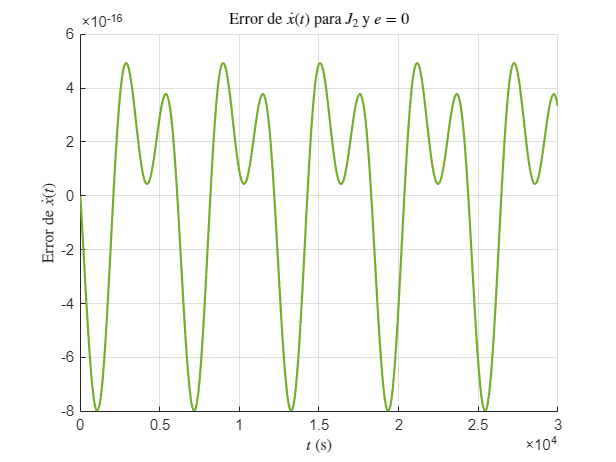

plotError(t, dx_K, dx_B, ang, 'Error de $\dot{x}(t)$ para $J_2$ y $e = 0$', '$t$ (s)', 'Error de $\dot{x}(t)$', "#77AC30");

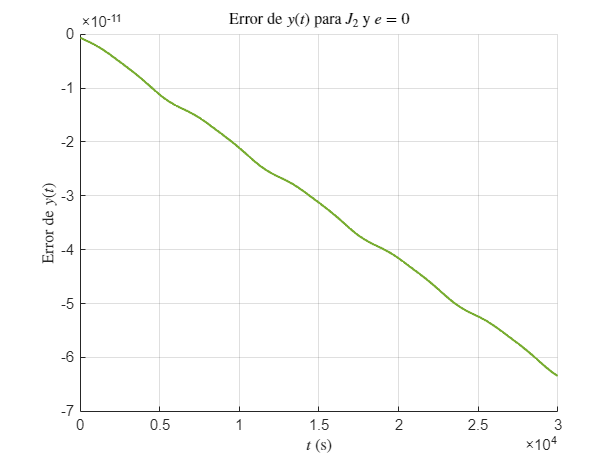

plotError(t,  y_K,  y_B, ang,       'Error de $y(t)$ para $J_2$ y $e = 0$', '$t$ (s)',       'Error de $y(t)$', "#77AC30");

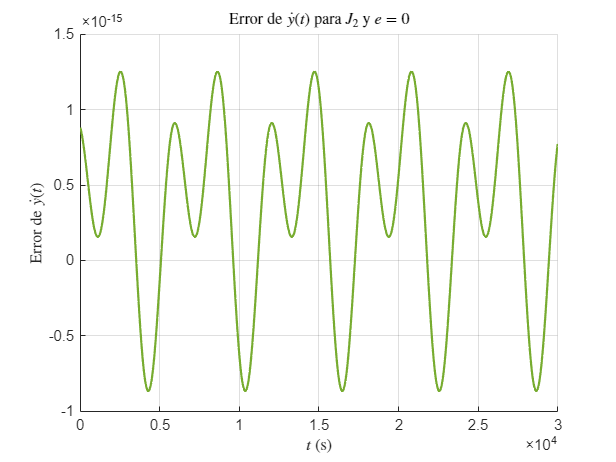

plotError(t, dy_K, dy_B, ang, 'Error de $\dot{y}(t)$ para $J_2$ y $e = 0$', '$t$ (s)', 'Error de $\dot{y}(t)$', "#77AC30");

## J3

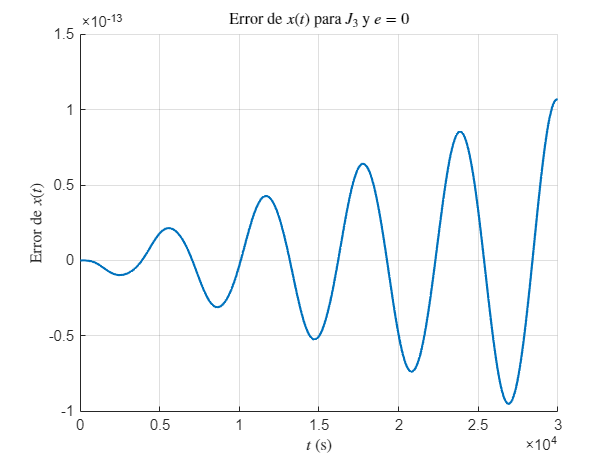

k1 = - n^2*J3*R^3/(2*a^2);
k2 = 15/4*si^3 - 3 * si;
k3 = 15/4*si^3;
K3 = dy0 + 2*n*x0 - (k1*k2*sw/n) + (k1*k3*s3w/(3*n));
kp3  = dx0 / n;
kpp3 = x0;
Kp3  = y0 - 2*dx0/n - 5*J3*R^3/(2*a^2) * ...
       (15/4*si^3*(cw - c3w/9) - 3*cw*si);
m1 = ci * (15/2*si^2 - 3);
m2 = 15/2*si^2*ci;
cp3  = dz0/n;
cpp3 = z0;

% x
x_K = kp3*snt + kpp3*cnt - k1*k2/n * ...
      (-cw*cnt*t + sw*snt*t + cw*snt/n) + ...
      k1*k3/(6*n^2) * ...
      (-s3w/2*c3nt + s3w/2*cnt - c3w/2*s3nt + 3/2*c3w*snt) + ...
      2*K3/n * (1 - cnt);
x_B = ((n + 6*n*sin((n*t)/2)^2)/n)*x0 + (sin(n*t)/n)*dx0 + ((4*sin((n*t)/2)^2)/n)*dy0 + (((15*R^3*n*sin(n*t)*sin(INC)^3*cos(omega))/8 - 6*R^3*n*sin((n*t)/2)^2*sin(INC)*sin(omega) - (15*R^3*n^2*t*sin(INC)^3*cos(omega))/8 - (5*R^3*n*sin(n*t)^3*sin(INC)^3*cos(omega))/8 - (15*R^3*n*sin(n*t)^2*sin(INC)^3*sin(omega))/8 + 15*R^3*n*sin((n*t)/2)^4*sin(INC)^3*sin(omega) - 15*R^3*n*sin((n*t)/2)^6*sin(INC)^3*sin(omega) - (3*R^3*n*sin(n*t)*sin(INC)*cos(omega))/2 + (3*R^3*n^2*t*sin(INC)*cos(omega))/2 + (5*R^3*n*sin(n*t)^2*sin(INC)^3*sin(omega)^3)/2 + 10*R^3*n*sin((n*t)/2)^2*sin(INC)^3*sin(omega)^3 - 20*R^3*n*sin((n*t)/2)^4*sin(INC)^3*sin(omega)^3 + 20*R^3*n*sin((n*t)/2)^6*sin(INC)^3*sin(omega)^3 + (15*R^3*n^2*t*sin(n*t)*sin(INC)^3*sin(omega))/8 + (15*R^3*n^2*t*sin((n*t)/2)^2*sin(INC)^3*cos(omega))/4 - (3*R^3*n^2*t*sin(n*t)*sin(INC)*sin(omega))/2 + (5*R^3*n*sin(n*t)^3*sin(INC)^3*cos(omega)*sin(omega)^2)/2 - 3*R^3*n^2*t*sin((n*t)/2)^2*sin(INC)*cos(omega))/(a^2*n))*J3;

% xdot
dx_K = n*kp3*cnt - n*kpp3*snt - k1*k2/n * ...
       (cw*nt*snt + sw*snt + sw*nt*cnt) + ...
       k1*k3/(6 * n^2) * ...
       (3*n/2*s3w*s3nt - n/2*s3w*snt - 3*n/2*c3w*c3nt + 3*n/2*c3w*cnt) + ...
       2*K3*snt;
dx_B = (6*n*cos((n*t)/2)*sin((n*t)/2))*x0 + cos(n*t)*dx0 + (4*cos((n*t)/2)*sin((n*t)/2))*dy0 + (((3*R^3*n^2*sin(INC)*cos(omega))/2 - (15*R^3*n^2*sin(INC)^3*cos(omega))/8 - (3*R^3*n^2*cos(n*t)*sin(INC)*cos(omega))/2 - (3*R^3*n^2*sin(n*t)*sin(INC)*sin(omega))/2 + (15*R^3*n^2*cos(n*t)*sin(INC)^3*cos(omega))/8 - 3*R^3*n^2*sin((n*t)/2)^2*sin(INC)*cos(omega) + (15*R^3*n^2*sin(n*t)*sin(INC)^3*sin(omega))/8 + (15*R^3*n^2*sin((n*t)/2)^2*sin(INC)^3*cos(omega))/4 - (15*R^3*n^2*cos(n*t)*sin(n*t)*sin(INC)^3*sin(omega))/4 - (15*R^3*n^2*cos(n*t)*sin(n*t)^2*sin(INC)^3*cos(omega))/8 + 5*R^3*n^2*cos(n*t)*sin(n*t)*sin(INC)^3*sin(omega)^3 + 10*R^3*n^2*cos((n*t)/2)*sin((n*t)/2)*sin(INC)^3*sin(omega)^3 + 30*R^3*n^2*cos((n*t)/2)*sin((n*t)/2)^3*sin(INC)^3*sin(omega) - 45*R^3*n^2*cos((n*t)/2)*sin((n*t)/2)^5*sin(INC)^3*sin(omega) - (3*R^3*n^3*t*cos(n*t)*sin(INC)*sin(omega))/2 - 6*R^3*n^2*cos((n*t)/2)*sin((n*t)/2)*sin(INC)*sin(omega) - 40*R^3*n^2*cos((n*t)/2)*sin((n*t)/2)^3*sin(INC)^3*sin(omega)^3 + 60*R^3*n^2*cos((n*t)/2)*sin((n*t)/2)^5*sin(INC)^3*sin(omega)^3 + (15*R^3*n^3*t*cos(n*t)*sin(INC)^3*sin(omega))/8 - 3*R^3*n^3*t*cos((n*t)/2)*sin((n*t)/2)*sin(INC)*cos(omega) + (15*R^3*n^3*t*cos((n*t)/2)*sin((n*t)/2)*sin(INC)^3*cos(omega))/4 + (15*R^3*n^2*cos(n*t)*sin(n*t)^2*sin(INC)^3*cos(omega)*sin(omega)^2)/2)/(a^2*n))*J3;

% y
y_K = 2*kp3*cnt - 2*kpp3*snt + ...
      k1*k2*(- 2*t/n*cw*snt - 2*t/n*sw*cnt + 3*sw/n^2*snt - 5*cw/n^2*cnt) - ...
      k1*k3/(6*n^2) * ...
      (s3w*snt - 3*c3w*cnt + s3w/3*s3nt - c3w/3*c3nt) - ...
      3*K3*t + 4*K3/n*snt + Kp3;
y_B = (-6*n)*x0*t + (6*sin(n*t))*x0 + y0 + (-(4*sin((n*t)/2)^2)/n)*dx0 - 3*dy0*t + ((4*sin(n*t))/n)*dy0 + ((18*R^3*n^2*sin(INC)*sin(omega) - 36*R^3*n^2*sin(n*t)*sin(INC) - 90*R^3*n^2*sin(INC)^3*sin(omega)^3 + 45*R^3*n^2*sin(n*t)*sin(INC)^3 + 45*R^3*n^2*sin(INC)^3*sin(omega) - 90*R^3*n^2*sin(omega/2)^2*sin(n*t)*sin(INC)^3 + 72*R^3*n^2*sin((n*t)/2)^2*sin(INC)*sin(omega) + 72*R^3*n^2*sin(omega/2)^2*sin(n*t)*sin(INC) - 90*R^3*n^2*sin((n*t)/2)^2*sin(INC)^3*sin(omega))/(a^2*n*12))*t*J3 + (-(200*R^3*n*sin((n*t)/2)^2*sin(INC)^3 - 5*R^3*n*sin(n*t)^2*sin(INC)^3 - 180*R^3*n*sin((n*t)/2)^2*sin(INC) + 45*R^3*n*sin(n*t)*sin(INC)^3*sin(omega) + 10*R^3*n*sin(omega/2)^2*sin(n*t)^2*sin(INC)^3 - 400*R^3*n*sin(omega/2)^2*sin((n*t)/2)^2*sin(INC)^3 - 90*R^3*n*sin(n*t)*sin(INC)^3*sin(omega)^3 + 15*R^3*n*sin(n*t)^3*sin(INC)^3*sin(omega) + 10*R^3*n*sin(n*t)^2*sin((n*t)/2)^2*sin(INC)^3 + 18*R^3*n*sin(n*t)*sin(INC)*sin(omega) + 360*R^3*n*sin(omega/2)^2*sin((n*t)/2)^2*sin(INC) + 20*R^3*n*sin(n*t)^2*sin(INC)^3*sin(omega)^2 - 20*R^3*n*sin(n*t)^3*sin(INC)^3*sin(omega)^3 + 100*R^3*n*sin((n*t)/2)^2*sin(INC)^3*sin(omega)^2 - 40*R^3*n*sin(n*t)^2*sin((n*t)/2)^2*sin(INC)^3*sin(omega)^2 - 20*R^3*n*sin(omega/2)^2*sin(n*t)^2*sin((n*t)/2)^2*sin(INC)^3 - 40*R^3*n*sin(omega/2)^2*sin(n*t)^2*sin(INC)^3*sin(omega)^2 - 200*R^3*n*sin(omega/2)^2*sin((n*t)/2)^2*sin(INC)^3*sin(omega)^2 + 80*R^3*n*sin(omega/2)^2*sin(n*t)^2*sin((n*t)/2)^2*sin(INC)^3*sin(omega)^2)/(a^2*n*12))*J3;

% ydot
dy_K = -2*n*kp3*snt - 2*n*kpp3*cnt + ...
       k1*k2 * (-2*cw*t*cnt + 2*t*sw*snt + sw/n*cnt + 3*cw/n*snt) - ...
       (k1*k3/(3*n)) * ...
       (s3w/2*cnt + 3/2*c3w*snt + s3w/2*c3nt + c3w/2*s3nt) - ...
       3*K3 + 4*K3*cnt;
dy_B = (-12*n*sin((n*t)/2)^2)*x0 + (-2*sin(n*t))*dx0 + (1 - 8*sin((n*t)/2)^2)*dy0 + ((R^3*n*sin(INC)*sin(omega)*(5*sin(INC)^2*sin(omega)^2 - 3))/(2*a^2) - (R^3*n*sin(omega + n*t)*sin(INC)*(5*sin(omega + n*t)^2*sin(INC)^2 - 3))/(2*a^2) - (2*((15*R^3*n*sin(n*t)*sin(INC)^3*cos(omega))/8 - 6*R^3*n*sin((n*t)/2)^2*sin(INC)*sin(omega) - (15*R^3*n^2*t*sin(INC)^3*cos(omega))/8 - (5*R^3*n*sin(n*t)^3*sin(INC)^3*cos(omega))/8 - (15*R^3*n*sin(n*t)^2*sin(INC)^3*sin(omega))/8 + 15*R^3*n*sin((n*t)/2)^4*sin(INC)^3*sin(omega) - 15*R^3*n*sin((n*t)/2)^6*sin(INC)^3*sin(omega) - (3*R^3*n*sin(n*t)*sin(INC)*cos(omega))/2 + (3*R^3*n^2*t*sin(INC)*cos(omega))/2 + (5*R^3*n*sin(n*t)^2*sin(INC)^3*sin(omega)^3)/2 + 10*R^3*n*sin((n*t)/2)^2*sin(INC)^3*sin(omega)^3 - 20*R^3*n*sin((n*t)/2)^4*sin(INC)^3*sin(omega)^3 + 20*R^3*n*sin((n*t)/2)^6*sin(INC)^3*sin(omega)^3 + (15*R^3*n^2*t*sin(n*t)*sin(INC)^3*sin(omega))/8 + (15*R^3*n^2*t*sin((n*t)/2)^2*sin(INC)^3*cos(omega))/4 - (3*R^3*n^2*t*sin(n*t)*sin(INC)*sin(omega))/2 + (5*R^3*n*sin(n*t)^3*sin(INC)^3*cos(omega)*sin(omega)^2)/2 - 3*R^3*n^2*t*sin((n*t)/2)^2*sin(INC)*cos(omega)))/a^2)*J3;

% z
z_K = cp3*snt + cpp3*cnt + ...
      k1*m1/n^2*(1 - cnt) - k1*m2/n^2 * ...
      (c2w*(1/3*cnt - c2nt/3) - s2w*(2/3*snt - 1/3*s2nt));
z_B = cos(n*t)*z0 + (sin(n*t)/n)*dz0 + (((15*R^3*cos(INC)^3)/4 - (9*R^3*cos(INC))/4 - (5*R^3*cos(2*omega)*cos(INC)^3)/4 + (9*R^3*cos(n*t)*cos(INC))/4 - (15*R^3*cos(n*t)*cos(INC)^3)/4 + (5*R^3*cos(2*omega)*cos(INC))/4 + (5*R^3*sin(2*omega)*cos(INC)^3*sin(n*t))/2 + (5*R^3*cos(2*omega)*cos(n*t)^2*cos(INC)^3)/2 + (5*R^3*cos(2*omega)*cos(n*t)*cos(INC))/4 - (5*R^3*sin(2*omega)*cos(INC)*sin(n*t))/2 - (5*R^3*cos(2*omega)*cos(n*t)^2*cos(INC))/2 - (5*R^3*cos(2*omega)*cos(n*t)*cos(INC)^3)/4 + (5*R^3*sin(2*omega)*cos(n*t)*cos(INC)*sin(n*t))/2 - (5*R^3*sin(2*omega)*cos(n*t)*cos(INC)^3*sin(n*t))/2)/a^2)*J3;

% zdot
dz_K = cp3*n*cnt - cpp3*n*snt + ...
         k1*m1/n * snt - k1*m2/n * ...
         (c2w * (- 1/3*snt + 2/3*s2nt) - ...
         s2w * (2/3*cnt - 2/3*c2nt));
dz_B = (-n*sin(n*t))*z0 + cos(n*t)*dz0 + (((15*R^3*n*cos(INC)^3*sin(n*t))/4 - (9*R^3*n*cos(INC)*sin(n*t))/4 - (5*R^3*n*cos(2*omega)*cos(INC)*sin(n*t))/4 - (5*R^3*n*sin(2*omega)*cos(n*t)*cos(INC))/2 + (5*R^3*n*sin(2*omega)*cos(n*t)^2*cos(INC))/2 + (5*R^3*n*cos(2*omega)*cos(INC)^3*sin(n*t))/4 + (5*R^3*n*sin(2*omega)*cos(n*t)*cos(INC)^3)/2 - (5*R^3*n*sin(2*omega)*cos(INC)*sin(n*t)^2)/2 - (5*R^3*n*sin(2*omega)*cos(n*t)^2*cos(INC)^3)/2 + (5*R^3*n*sin(2*omega)*cos(INC)^3*sin(n*t)^2)/2 - 5*R^3*n*cos(2*omega)*cos(n*t)*cos(INC)^3*sin(n*t) + 5*R^3*n*cos(2*omega)*cos(n*t)*cos(INC)*sin(n*t))/a^2)*J3;

plotError(t,  x_K,  x_B, ang,       'Error de $x(t)$ para $J_3$ y $e = 0$', '$t$ (s)',       'Error de $x(t)$', "#0072BD");

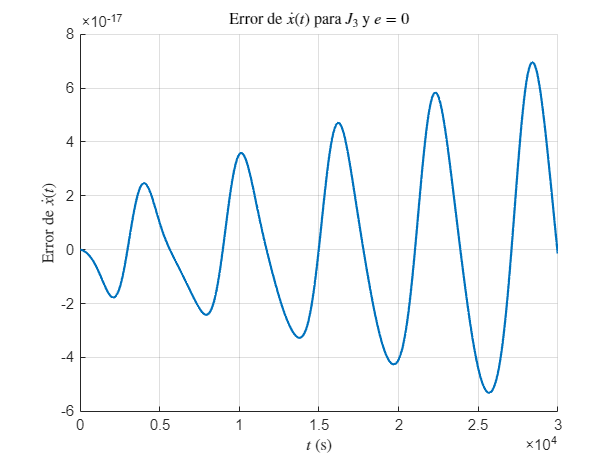

plotError(t, dx_K, dx_B, ang, 'Error de $\dot{x}(t)$ para $J_3$ y $e = 0$', '$t$ (s)', 'Error de $\dot{x}(t)$', "#0072BD");

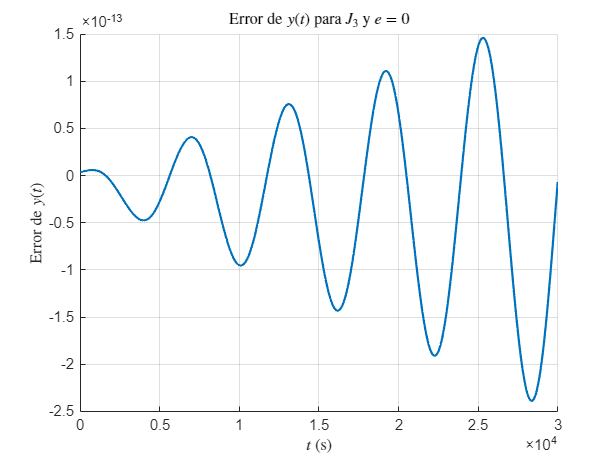

plotError(t,  y_K,  y_B, ang,       'Error de $y(t)$ para $J_3$ y $e = 0$', '$t$ (s)',       'Error de $y(t)$', "#0072BD");

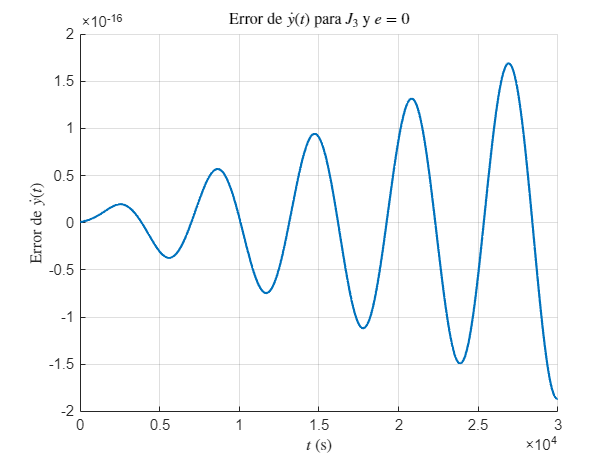

plotError(t, dy_K, dy_B, ang, 'Error de $\dot{y}(t)$ para $J_3$ y $e = 0$', '$t$ (s)', 'Error de $\dot{y}(t)$', "#0072BD");

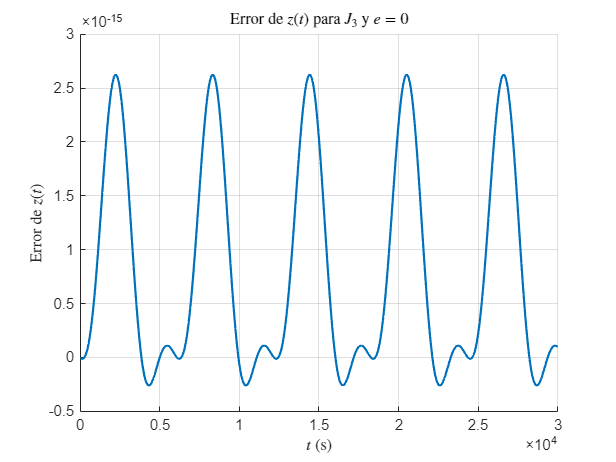

plotError(t,  z_K,  z_B, ang,       'Error de $z(t)$ para $J_3$ y $e = 0$', '$t$ (s)',       'Error de $z(t)$', "#0072BD");

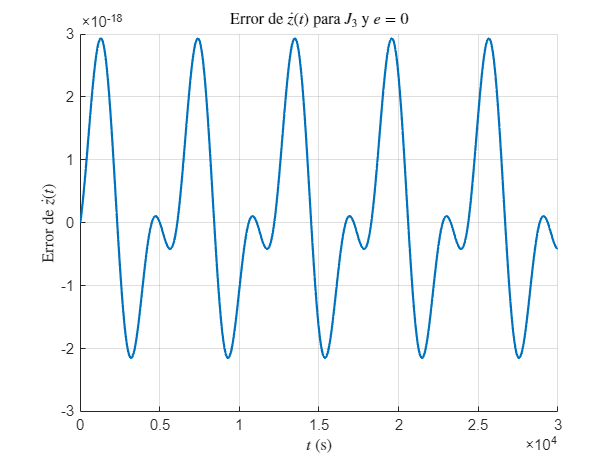

plotError(t, dz_K, dz_B, ang, 'Error de $\dot{z}(t)$ para $J_3$ y $e = 0$', '$t$ (s)', 'Error de $\dot{z}(t)$', "#0072BD");